clc
clearvars

prot = NaN(7,1);
prot(1) = 39.4843;
prot(2) = -100;
prot(3) = 10;
prot(4) = 10;
prot(5) = 140;
prot(6) = -70;
prot(7) = 10;

tt = 1:0.5:(prot(3)+prot(5)+prot(7));
v = [];
for i = 1:length(tt)
    v = arrayfun(@(t)volt_clamp(t,prot),tt(1:i));
    if mod(i,50) == 0
        disp("break point")
    end
end

break point
break point
break point
break point
break point
break point


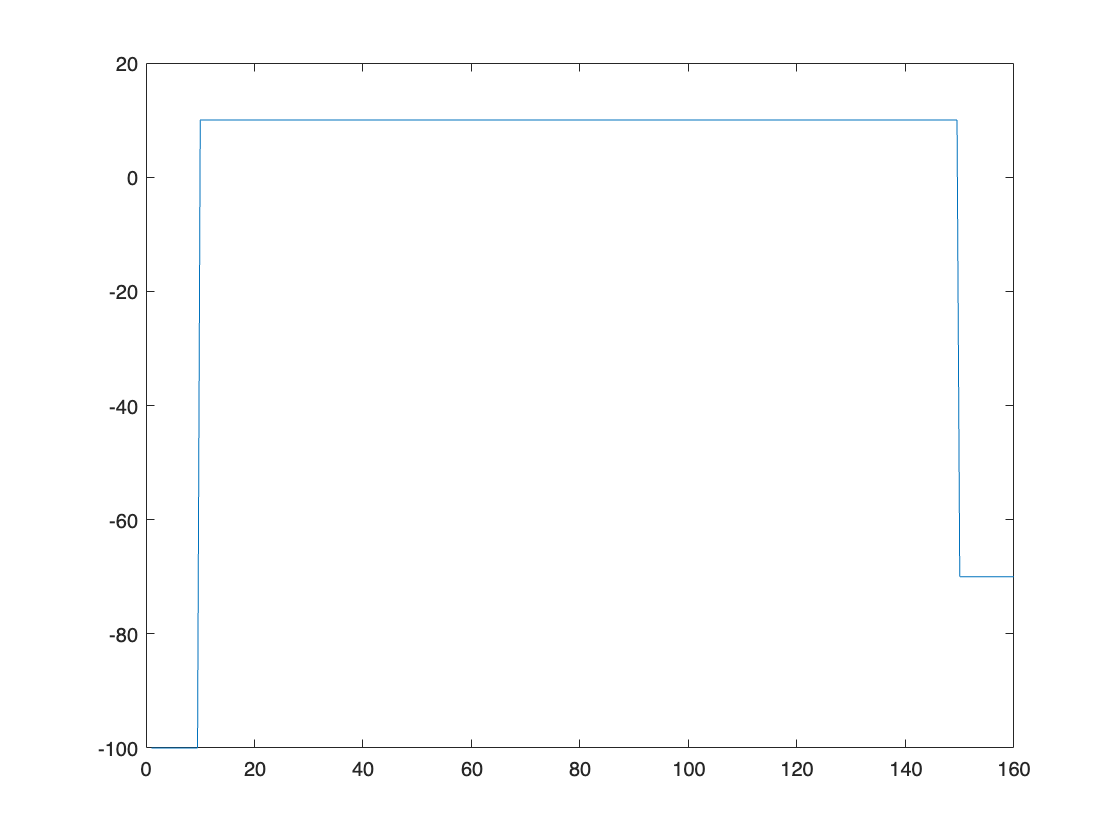

v = arrayfun(@(t)volt_clamp(t,prot),tt);
plot(tt,v)

function vc = volt_clamp(t,prot)
    % Generate voltage-clamp protocol
    holdp = prot(2);
    holdt = prot(3);
    p1 = prot(4);
    p1t = prot(5);
    p2 = prot(6);
    if (t < holdt)
        vc = holdp;
    elseif (t >= holdt) && (t < (holdt+p1t))
        vc = p1;
    else
        vc = p2;
    end
end